# Classify Product Reviews Using Convolutional Neural Network

To classify text data using Convolutional Neural Network, the text must be converted to image. Reviews are padded or truncated to a constant length *S* and then converted into sequences of word vectors of length *C* using a word embedding. The reviews are now represented as 1-by-*S*-by-*C* image - an image with height 1, width *S*, and *C* depth.

This code trains a network with 1-D convolutional filters of varying widths. The width of each filter corresponds to an n-gram length of words. The network has multiple branches of convolutional layers, so it can use different n-gram lengths. 

## Load Pretrained Word Embedding

Load the pretrained fastText word embedding. Model *for fastText English 16 Billion Token Word Embedding* support package. If this support package is not installed, then the function provides a download link.  

clear variables;                % Clear workspace at start
emb = fastTextWordEmbedding;    % Load word embedding that uses fasttext
numFeatures = emb.Dimension;    % The number of features is determined by the word embedding dimension

Variables for tuning the training

sql = 128;                      % sequence length
numFilters = 256;               % number of filters
ngramLengths = [2 3 4 5];       % ngramlengths
miniBatchSize = 256;            % mini batch size
ilr = 0.1;                      % initial learning rate
maxEpochs = 50;                 % number of trainng epochs
gdf = 0.9;                      % set gradient decay factor
sgdf = 0.9;                     % set value for squared gradient factor

## Load Data

ReadTrain = "Furniture_Train.csv";                              % Read the data from file
data2 = readtable(ReadTrain,"VariableNamingRule","preserve");   % Insert the read data into a Matlab table


Read the labels from the data and find the unique class names.

% Categorize data labels
DataLabels0 = data2{:, "HumanSentiment"};
classNames0 = unique(DataLabels0);
DataLabels_Categorical2 = categorical(DataLabels0,classNames0);

idxs = DataLabels_Categorical2 ~= 'NO ISSUES';

DataLabels2 = categorical(data2{idxs, "RecallStatus"});
classNames2 = unique(DataLabels2);

% Extract text of reviews
ReviewText2 = data2{idxs, "ReviewText"};

numObservations2 = numel(DataLabels2);

## Preprocess Text

% Tokenize the text.
documents = tokenizedDocument(ReviewText2);

% Convert the text to lowercase.
documents = lower(documents);

% Erase punctuation.
documents = erasePunctuation(documents);

% Remove tokens containing digits.
pat = textBoundary + wildcardPattern + digitsPattern + wildcardPattern + textBoundary;
documents = replace(documents,pat,"");

% Stem and lemmatize
documents = addPartOfSpeechDetails(documents);
documents = removeStopWords(documents);
documents = normalizeWords(documents,'Style','lemma');

% Fix mis-spelled words
documents = correctSpelling(documents);

% Remove 1 character words
documents = removeShortWords(documents, 1)

documents =   1969×1 tokenizedDocument:

     22 tokens: get down put last drawer together find manufacturer drill hole incorrectly drawer side late send back drawer tacky need item week ago
     76 tokens: even bad review decide go against gut purchase dresser grant cheap tax come around put almost dresser together notice drawer side miss tempt take dresser back whole part get replacement hopefully part need package specify miss part contact company try replacement part order online luck keep tell part incorrect way stupid call number type still wait hold minute feel like wait IRS cheap dresser save purchase expensive may well purchase same price try true another consumer
     29 tokens: return item work baby insert really change feel halo baby expect rest slightly mattress baby feel cradle like hammock once place sink right down just lay mattress like previous
      7 tokens: send baby bouncer friend gift baby 

Prepare documents for sizing to fit CNN

Converts data into a table containing the predictors and the responses. The predictors are 1-by-`sequenceLength`-by-*C* arrays of word vectors given by the word embedding `emb.`

% Convert documents to embeddingDimension-by-sequenceLength-by-1 images.
predictors2 = doc2sequence(emb,documents,'Length',sql, "PaddingDirection","right");


% Reshape images to be of size 1-by-sequenceLength-embeddingDimension.
predictors2 = cellfun(@(X) permute(X,[3 2 1]),predictors2,'UniformOutput',false);

Set training data

dataTrain2 = table;
dataTrain2.Predictors = predictors2;
dataTrain2.Responses = DataLabels2;

## Define Network Architecture

Define the network architecture for the classification task.

The following steps describe the network architecture.

- Specify an input size of 1-by-*S*-by-*C*, where *S* is the sequence length and *C* is the number of features.

- For the n-gram lengths 2, 3, 4, and 5, create blocks of layers containing a convolutional layer, a batch normalization layer, a ReLU layer, a dropout layer, and a max pooling layer.

- For each block, specify nf convolutional filters of size 1-by-*N* and pooling regions of size 1-by-*S*, where *N* is the n-gram length and nf is the number of filters.

- Connect the input layer to each block and concatenate the outputs of the blocks using a depth concatenation layer.

- To classify the outputs, include a fully connected layer with output size *K*, a softmax layer, and a classification layer, where *K* is the number of classes.

First, in a layer array, specify the input layer, the first block for unigrams, the depth concatenation layer, the fully connected layer, the softmax layer, and the classification layer.

inputSize = [1 sql numFeatures];
numBlocks = numel(ngramLengths);
numClasses = numel(classNames2);

Create a layer graph containing the input layer. Set the normalization option to `'none'` and the layer name to `'input'`.

layer = imageInputLayer(inputSize,'Normalization','none','Name','input'); 
lgraph = layerGraph(layer);

For each of the n-gram lengths, create a block of convolution, batch normalization, ReLU, dropout, and max pooling layers. Connect each block to the input layer.

for j = 1:numBlocks
    N = ngramLengths(j);
    
    block = [
        convolution2dLayer([1 N],numFilters,'Name',"conv"+N,'Padding','same')
        batchNormalizationLayer('Name',"bn"+N)
        reluLayer('Name',"relu"+N)
        dropoutLayer(0.2,'Name',"drop"+N)
        maxPooling2dLayer([1 sql],'Name',"max"+N)];
    
    lgraph = addLayers(lgraph,block);
    lgraph = connectLayers(lgraph,'input',"conv"+N);
end

View the network architecture in a plot.

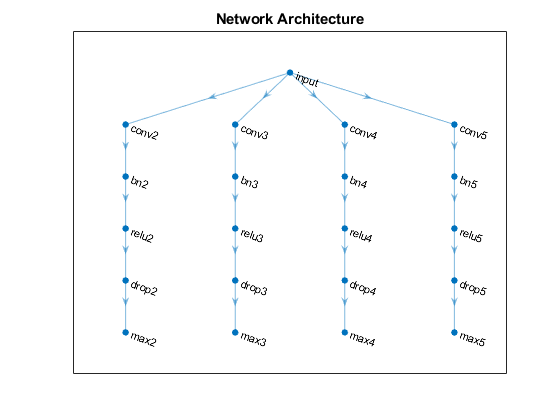

figure
plot(lgraph)
title("Network Architecture")

Add the depth concatenation layer, the fully connected layer, the softmax layer, and the classification layer. 

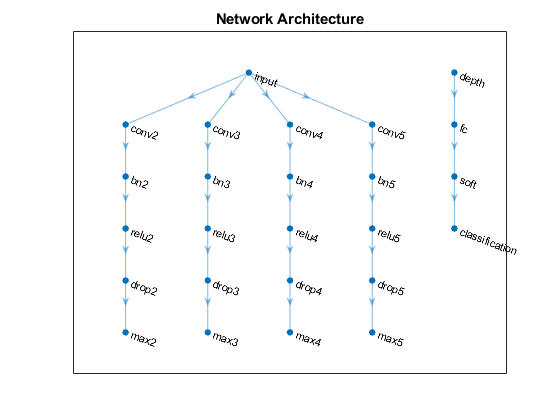

layers = [
    depthConcatenationLayer(numBlocks,'Name','depth')
    fullyConnectedLayer(numClasses,'Name','fc')
    softmaxLayer('Name','soft')
    classificationLayer('Name','classification')];

lgraph = addLayers(lgraph,layers);

figure
plot(lgraph)
title("Network Architecture")

Connect the max pooling layers to the depth concatenation layer and view the final network architecture in a plot.

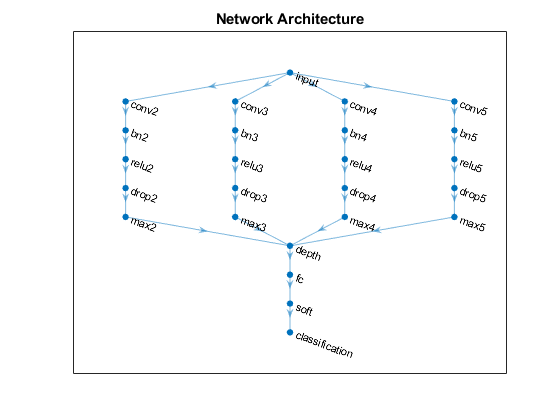

for j = 1:numBlocks
    N = ngramLengths(j);
    lgraph = connectLayers(lgraph,"max"+N,"depth/in"+j);
end

figure
plot(lgraph)
title("Network Architecture")

## Train Network

Specify the training options:

- Train with a mini-batch size of 128.

- Do not shuffle the data because the datastore is not shuffleable.

- Display the training progress plot and suppress the verbose output.

numIterationsPerEpoch = floor(numObservations2/miniBatchSize);

options = trainingOptions('adam', ... 
    'MiniBatchSize',512, ...
    'Shuffle','never', ...
    'InitialLearnRate', 11.051, ...
    'MaxEpochs', 19, ...
    "LearnRateSchedule","none", ...
    'Plots','training-progress', ...
    'Verbose',false); 


Train the network using the `trainNetwork` function.

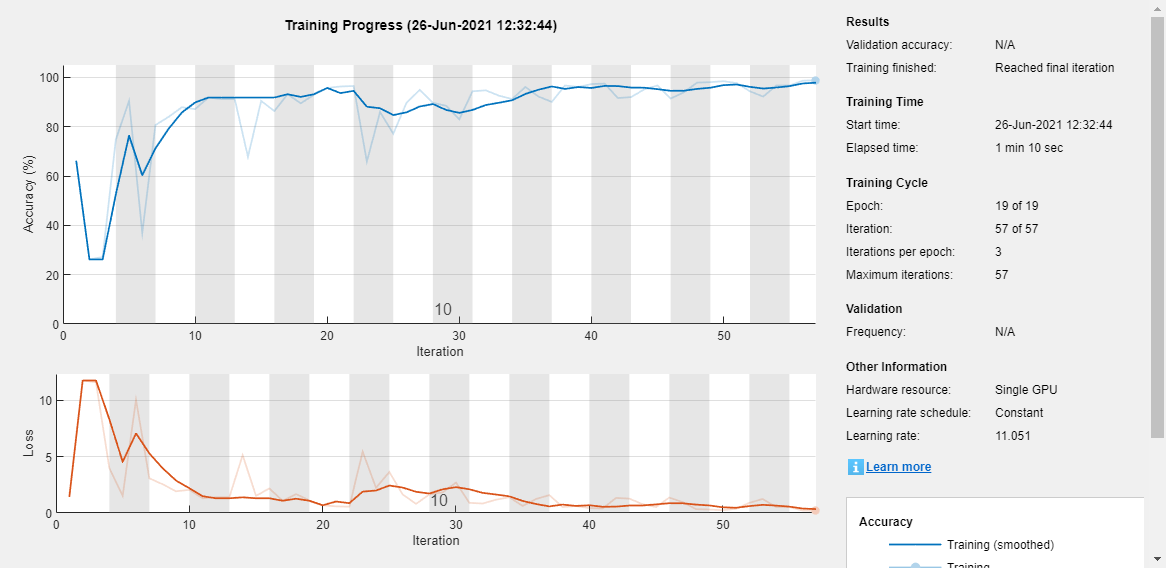

net = trainNetwork(dataTrain2,lgraph,options);

## Predict Using New Data

Classify the event type of three new reviews. Create a string array containing the new reviews.

reportsN = readtable("Furniture_Test.csv","VariableNamingRule","preserve")

reportsN = 545×13 table
    UniqueID      ReviewID     InitialPublishDate    Product ID                                                       ProductName                                                             BazaarVoice_Category                                                                                                                                                                                                                                                                                                      ReviewText                                                                                                                                                                                                                                                                                                  RecallStatus      GroupedCat


DataLabels00 = reportsN{:, "HumanSentiment"};
DataLabels_Categorical00 = categorical(DataLabels00,classNames0)

DataLabels_Categorical00 = 545×1 categorical array
     NO ISSUES 
     NO ISSUES 
     NO ISSUES 
     NO ISSUES 
     NO ISSUES 
     NO ISSUES 
     NO ISSUES 
     NO ISSUES 
     NO ISSUES 
     QUALITY ISSUES 
     QUALITY ISSUES 
     QUALITY ISSUES 
     QUALITY ISSUES 
     QUALITY ISSUES 
     NO ISSUES 
     NO ISSUES 
     QUALITY ISSUES 
     NO ISSUES 
     QUALITY ISSUES 
     NO ISSUES 
     NO ISSUES 
     NO ISSUES 
     NO ISSUES 
     NO ISSUES 
     QUALITY ISSUES 
     NO ISSUES 
     NO ISSUES 
     NO ISSUES 
     NO ISSUES 
     QUALITY ISSUES 



IDXnqs = DataLabels_Categorical00 ~= 'NO ISSUES'

IDXnqs = 545×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1


reportsNew = reportsN{IDXnqs, "ReviewText"}

reportsNew = 219×1 cell array
    {'The bassinet is nice.one of the baskets in the bottom were broken but I dont care much I wont be using them anyway. It was a great price for the first two to three months that it will be used.'                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                   

labelsNew = categorical(reportsN{IDXnqs, "RecallStatus"});


Preprocess the text data using the preprocessing steps as the training documents.

% Tokenize the text.
documents = tokenizedDocument(reportsNew);

% Convert the text to lowercase.
documents = lower(documents);

% Erase punctuation.
documents = erasePunctuation(documents);

% Remove tokens containing digits.
pat = textBoundary + wildcardPattern + digitsPattern + wildcardPattern + textBoundary;
documents = replace(documents,pat,"");

% Stem and lemmatize
documents = addPartOfSpeechDetails(documents);
documents = removeStopWords(documents);
documents = normalizeWords(documents,'Style','lemma');

% Fix mis-spelled words
documents = correctSpelling(documents);

% Remove 1 character words
documents = removeShortWords(documents, 1)

documents =   219×1 tokenizedDocument:

     14 tokens: bassinet nice basket bottom break care wont anyway great price first two three month
     29 tokens: love though mattress thin daughter sleep couple time like volume button music vibration come broke work hate music vibration last like min cute like mainly become storage daughter thing
      7 tokens: work month change battery still work disappointed
     28 tokens: buy dresser old daughter two month dresser stay fall apart draw bottom start bend draw start fall apart piece piece put back together basically buy unless baby clothes
     26 tokens: love month old year old love bouncer keep month baby quite hour keep yr old daughter busy put bouncer together really easy buy another wont fright
     44 tokens: like bouncer mostly vibration bounce little difficult bounce vibration nice strong pair white noise sound set calm infant right down love fold con hard bo

Prepare documents for sizing to fit CNN

Converts data into a table containing the predictors and the responses. The predictors are 1-by-`sequenceLength`-by-*C* arrays of word vectors given by the word embedding `emb.`

% Convert documents to embeddingDimension-by-sequenceLength-by-1 images.
predictors = doc2sequence(emb,documents,'Length',sql, "PaddingDirection","right");

% Reshape images to be of size 1-by-sequenceLength-embeddingDimension.
predictors = cellfun(@(X) permute(X,[3 2 1]),predictors,'UniformOutput',false); 

Classify the new sequences using the trained LSTM network.

XNew = table;
XNew.Predictors = predictors;

predictionsNew = classify(net,XNew)

predictionsNew = 219×1 categorical array
     Not Recalled 
     Not Recalled 
     Not Recalled 
     Recalled 
     Not Recalled 
     Not Recalled 
     Not Recalled 
     Not Recalled 
     Not Recalled 
     Recalled 
     Not Recalled 
     Not Recalled 
     Not Recalled 
     Not Recalled 
     Not Recalled 
     Recalled 
     Not Recalled 
     Not Recalled 
     Not Recalled 
     Not Recalled 
     Not Recalled 
     Not Recalled 
     Recalled 
     Recalled 
     Not Recalled 
     Recalled 
     Not Recalled 
     Not Recalled 
     Not Recalled 
     Recalled 


Check Accuracy

AccCNN = sum(labelsNew == predictionsNew)/numel(labelsNew == predictionsNew)

AccCNN = 0.9087

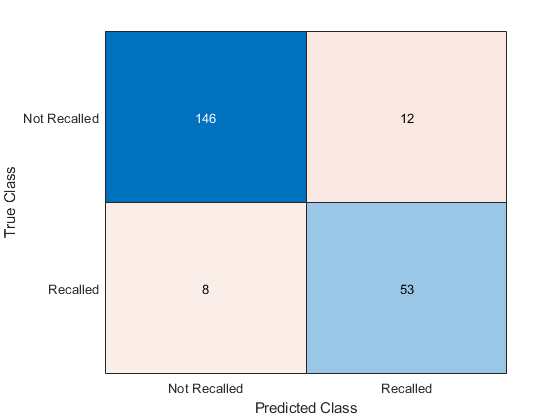


confusionchart(categorical(labelsNew), predictionsNew)


cm = confusionmat(categorical(labelsNew), predictionsNew)

cm =    146    12
     8    53


## Preprocess Reviews Function

The `preprocessReviews `function takes text data from the reviews, and processes it to a form that is suitable for machine operations.

The `PreProcesedReviews` function takes text data and performs these steps:

- Tokenize the text.

- Convert the text to lowercase.

- Erase punctuation

- Remove tokens containing digits

- Stem and lemmatize

- Fix mis-spelled words

- Remove 1 character words

function PreProcesedReviews = preprocessReviews(ReviewText)

    % Tokenize the text.
    documents = tokenizedDocument(ReviewText);
    
    % Convert the text to lowercase.
    documents = lower(documents);
    
    % Erase punctuation.
    documents = erasePunctuation(documents);
    
    % Remove tokens containing digits.
    pat = textBoundary + wildcardPattern + digitsPattern + wildcardPattern + textBoundary;
    documents = replace(documents,pat,"");
    
    % Stem and lemmatize
    documents = addPartOfSpeechDetails(documents);
    documents = removeStopWords(documents);
    documents = normalizeWords(documents,'Style','lemma');
    
    % Fix mis-spelled words
    documents = correctSpelling(documents);
    
    % Remove 1 character words
    documents = removeShortWords(documents, 1);
    
    % Assign function output
    PreProcesedReviews = documents;
end